# ME5554/AOE5754/ECE5754 Applied Linear Systems - Final Project

Md Riasat Morshed Khan    

12/13/24

## Problem 1 [2 pts].  Prepare the Open-Loop Plant

The state-space LTI object that was developed in the Midterm Project for the open-loop plant should have been saved in a  .mat file.  Before you work on the Final Project, you are responsible for correcting any errors you had in your open-loop plant!  

a)  Load the open-loop plant from a .mat file.  Do NOT include code to regenerate the open-loop LTI state-space plant in this LiveScript!!!

After loading the .mat file, display the open-loop numerical state-space model.  This model MUST display appropriately chosen statenames, inputnames, and outputnames.  This is important to clearly identify the ordering of states you have chosen.

olsys = load('sys.mat');
load('ForceLimit.mat'); % Force and Torque Limit is saved on a different .mat file

b)  Extract the Aol, Bol, Col, and Dol matrices and save them in the Matlab workspace.  Do not display these results (because you already displayed them in the previous step).

Aol = olsys.A;
Bol = olsys.B;
Col = olsys.C;
Dol = olsys.D;

c)  Compute the open-loop eigenvalues (ol_poles), and the system dimensions (N, M, P).  Assign these quantities to variables for use later in the LiveScript, but do not display them here.

ol_poles = eig(Aol);
N = size(Aol,1);
M = size(Bol, 2);
P = size(Col,1);

## Problem 2 [5 pts].  Simulate Closed-Loop Control

You are given the following set of desired closed-loop poles which are known to result in 5% settling times (transient times) that are less than 200 seconds without saturating any of the control signals.

cl_poles = [-0.02+j*0.004, -0.02-j*0.004, ...
            -0.255+j*0.052, -0.255-j*0.052, ...
            -0.49+1i*0.099, -0.49-j*0.099];

a)  Use the `PLACE` function to compute the full state feedback control gain matrix, and display your result.

G_sys = place(Aol,Bol,cl_poles)

b)  Define an initial state vector using the exact same initial conditions that were defined in the Midterm project.

% Initial Vector as the MidTerm Project
init_vector = [50,-0.1,50,0.1,0,-0.01];

c)  Assume that you have access to the full state vector, then construct a closed-loop state-space LTI object using the feedback gains from 2a.  You must augment the output equation to include the original outputs as well as the control signals.  Simulate the initial value response using `INITIAL`.  Choose a final simulation time of 300 seconds for this simulation.  Estimate the 5% settling (transient) times for each output.  Generate a plot like what was required for the Midterm Project with the three outputs on the left-hand side (separate axes for each output), and the control signals on the right-hand side of the figure (separate axes for each control signal).  Annotate each plot with some kind of marker (e.g. xline) for the 5% settling times, the min and max allowable control signals (yline), grid lines, axis labels, and signal units.

C_augCL = [Col; -G_sys];

G_sys = 1.0e+09 *

   -0.0000   -0.0028    0.0000   -0.0031   -0.0135    0.0098
   -0.0000    0.1208   -0.0000    0.0001    0.6021   -1.1005


D_augCL = [Dol; zeros(2,2)];
Acl = Aol-Bol*G_sys;
Ccl = C_augCL-D_augCL*G_sys;
cl_sys = ss(Acl,[],C_augCL,[]);
t = linspace(0,300,1000);

[y,tOut] = initial(cl_sys,init_vector,t);
settlingTime_lsim = zeros(size(y,2));
for i = 1:size(y,2)
    S = lsiminfo(y(:,i),tOut,y(end,i),y(1,i),"SettlingTimeThreshold",0.05);
    settlingTime_lsim(i) = S.SettlingTime;
    fprintf('The settling Time for y(%d) is = %2.3f\n',i, S.SettlingTime);
end
S3 = lsiminfo(y(:,3),tOut,y(end,3),y(1,3),"SettlingTimeThreshold",0.05); %Since theta starts from 0- that's why instead of using SettlingTime, TransientTime was used
settlingTime_lsim(3) = S3.TransientTime 

## Comment: 

The response with the closed loop system did not result in less than 200 seconds of 5% settling time as you can see in the above print statements! which also resulted in more than 200 seconds of 5%settling time for angular displacement ($\theta \;$) in Problem (5e) 

The settling Time for y(1) is = 88.665
The settling Time for y(2) is = 166.247
The settling Time for y(3) is = 296.369
The settling Time for y(4) is = 282.083
The settling Time for y(5) is = 141.908


clf;
figure('Units','normalized','Position',[5,5,0.8,0.8]);

settlingTime_lsim =    88.6652         0         0         0         0
  166.2473         0         0         0         0
  115.6082         0         0         0         0
  282.0830         0         0         0         0
  141.9080         0         0         0         0


subplot(3,2,1);
plot(tOut, y(:,1), 'LineWidth', 1.5);
hold on;
xline(settlingTime_lsim(1), 'r:', 'LineWidth', 1.5, 'Label', num2str(settlingTime_lsim(1)), ...
    'LabelOrientation', 'aligned', 'FontSize', 8, 'DisplayName','SettlingTime');
hold off;
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]


subplot(3,2,3);
plot(tOut, y(:,2), 'LineWidth', 1.5);
hold on;
xline(settlingTime_lsim(2), 'r:', 'LineWidth', 1.5, 'Label', num2str(settlingTime_lsim(2)), ...
    'LabelOrientation', 'aligned', 'FontSize', 8, 'DisplayName','SettlingTime');
hold off;
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);

subplot(3,2,5);
plot(tOut, rad2deg(y(:,3)), 'LineWidth', 1.5);
hold on;
xline(settlingTime_lsim(3), 'r:', 'LineWidth', 1.5, 'Label', num2str(settlingTime_lsim(3)), ...
    'LabelOrientation', 'aligned', 'FontSize', 8, 'DisplayName','SettlingTime');
hold off;
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);
% Plot Variational Thrust Control
subplot(2,2,2);
plot(tOut, y(:,4), 'LineWidth', 1.5); % Use dashed line for the zero line
hold on;
yline(Fmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Fmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
ylim([-2.5e8,2.5e8]);
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);

plot(tOut, y(:,5), 'LineWidth', 1.5);
hold on;
yline(Tmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Tmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
ylim([-2.5e8,2.5e8]);
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('Closed Loop Response for a MIMO System');

d)  Display the animation plot as documentation of the performance.

als_f24_animate(tOut, y(:,1), y(:,2), y(:,3));

## Problem 3 [3 pts].   Evaluate Observability

a)  Show that this system is completely observable using all three outputs.  Justify your answer.

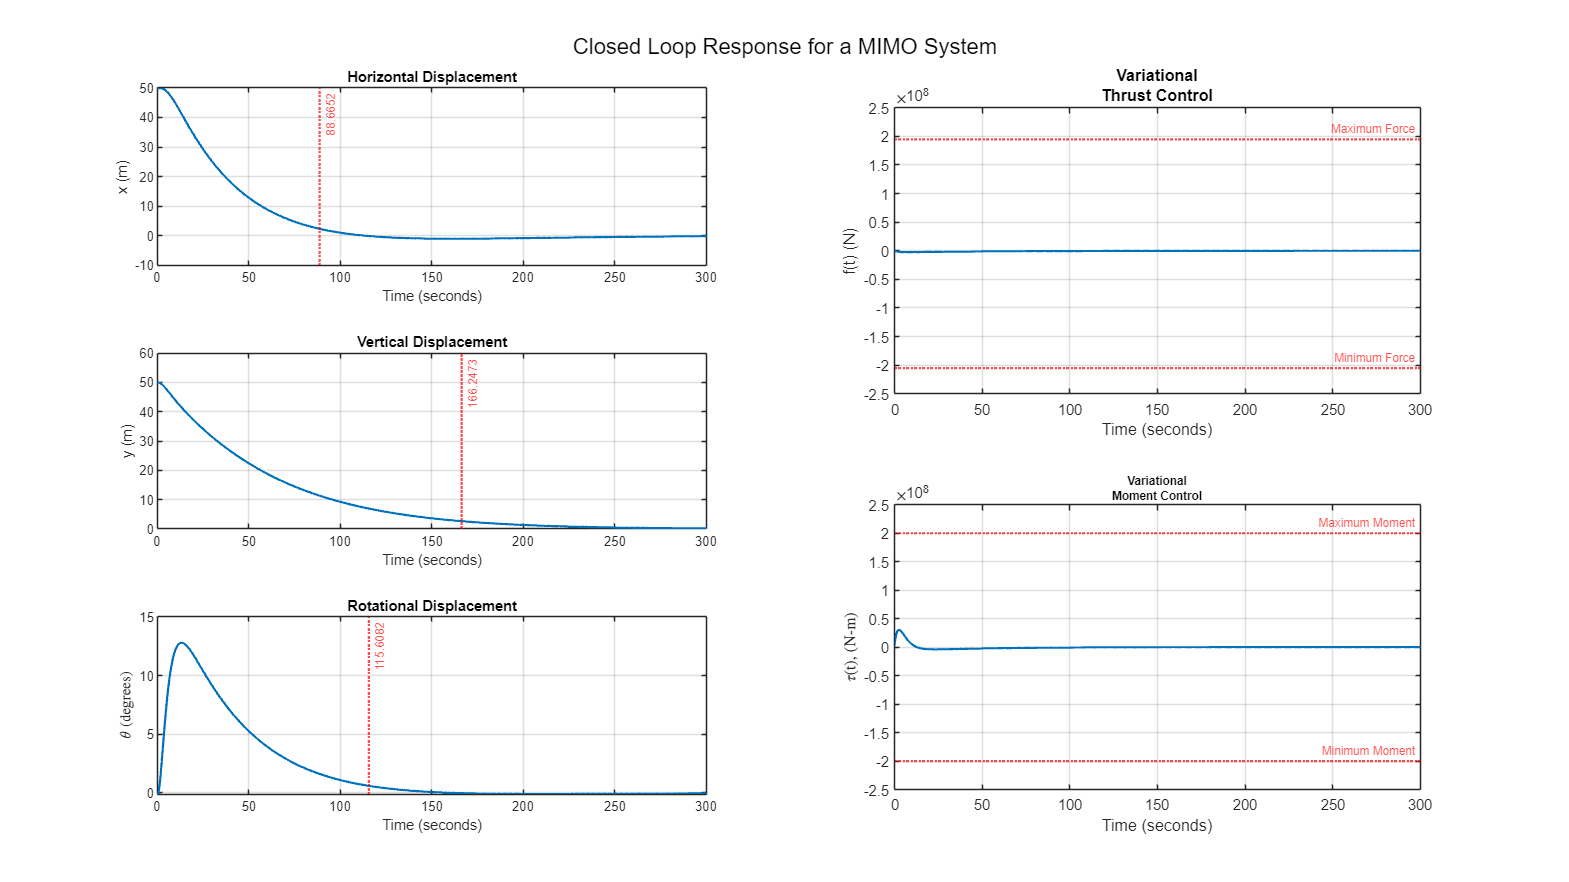

obs_matrix = obsv(Acl, Ccl(1:3,:));
if rank(obs_matrix) == size(Acl, 1)
    fprintf('The system is observable with all 3 output\n');
else

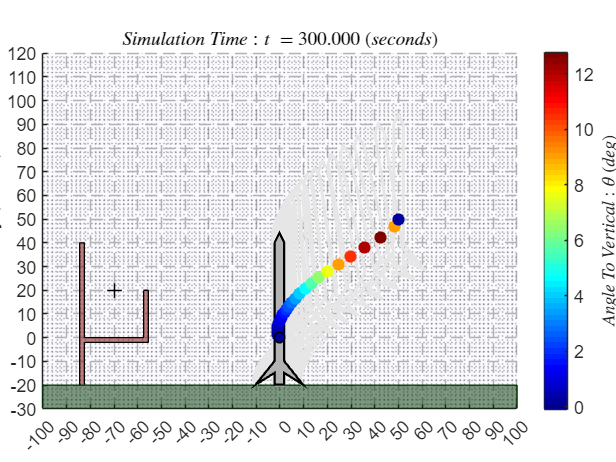

    fprintf('The system is not observable with all 3 output\n');
end

b)  Determine whether this system is completely observable using any subset of outputs.  Justify your answers.

N = size(olsys.A,1);
M = size(olsys.B,2);
P = size(olsys.C,1);

count = 1;
for number_of_outputs = 1:P

The system is observable with all 3 output


    indx = nchoosek([1:P],number_of_outputs);
    K = size(indx,1);
    for k = 1:K
        % Create a reduced system for the selected subset of outputs
        sys_reduced = ss(olsys.A, olsys.B, olsys.C(indx(k,:),:), olsys.D(indx(k,:),:));

        % Compute the observability matrix
        Q = obsv(sys_reduced);

        fprintf('rank(Q) = %d, subset = [ ',rank(Q));
        for i = 1:length(indx(k,:))
            fprintf(' y%d ',indx(k,i));
        end
        fprintf(']\n');
        count = count + 1;
    end
end

rank(Q) = 4, subset = [ 

 y1 

]


rank(Q) = 2, subset = [ 

 y2 

]


rank(Q) = 2, subset = [ 

 y3 

]


rank(Q) = 6, subset = [ 

 y1  y2 

]


rank(Q) = 4, subset = [ 

 y1  y3 

]


rank(Q) = 4, subset = [ 

 y2  y3 

]


rank(Q) = 6, subset = [ 

 y1  y2  y3 

]


## Explanation:

As we can see that first three subset consist of only one output corresponding to $y_1 ,y_2 \;\textrm{and}\;y_3$ only. And they are not completely observable. Same goes for the combination of $\left\lbrack y_1 \;y_3 \right\rbrack \;$and$\left\lbrack y_2 \;y_3 \right\rbrack$. Because their observability matrix have rank of 4 whereas the rank of A matrix is 6. Because of that rank deficiency, we can say that these combination is not observable. 

On the other hand, as we say is Problem (3a), the system is fully observable with all three outputs that is, with $\left\lbrack y_1 {\;y}_2 \;y_3 \right\rbrack$. and also for the combination of $\left\lbrack y_1 \;\;y_2 \right\rbrack$.

## Problem 4 [3 pts].  Design a Full-Order Luenberger Observer

a)  Select appropriate pole locations for the state estimator (observer)

## Explanation:

The way observer poles are selected is I just subtracted 2 from the closed-loop poles


obsv_pole = cl_poles - 2; %subtracted an offset from the closed loop pole


b)  Compute and display the associated observer feedback gain matrix using the `PLACE` function.

obsv_gains = place(Aol',Col',obsv_pole)'

obsv_gains =     2.3468    0.0666   -0.0143
    0.0292    0.0178   -9.8181
    0.4116   -1.3547   -0.2206
   -1.5065   13.5115    0.8662
    0.0167    0.0251    1.5379
   -0.0173   -0.0268    0.4816


c)  Generate a plot that includes the open-loop poles from Problem 1, the closed-loop poles from Problem 2, and observer poles from Problem 4.  Use common markers for each set of poles (i.e. all open-loop poles must use the same marker, etc.) so that it is easy to distinguish the poles on the figure.  Include a legend that only has three entries in it (open-loop, closed-loop, observer), corresponding to the three sets of poles.  You must use the `SGRID` function (read the Matlab help!!) to generate appropriate grid lines.  Annotate your plot with axis labels.  Make sure your legend does not cover up any of the poles!

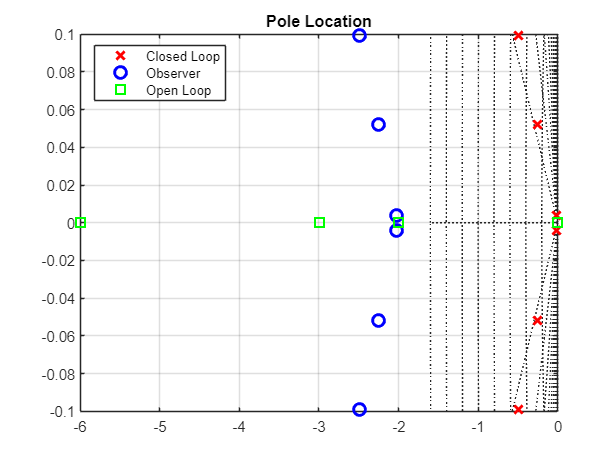

figure;
hold on;

sgrid; 

p1 = plot(real(cl_poles), imag(cl_poles), 'rx', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Closed Loop');
p2 = plot(real(obsv_pole), imag(obsv_pole), 'bo', 'MarkerSize', 8,  'LineWidth', 2, 'DisplayName', 'Observer');
p3 = plot(real(ol_poles), imag(ol_poles), 'gs', 'MarkerSize', 8,  'LineWidth', 2, 'DisplayName', 'Open Loop');

% Explicitly controlling the legend to only include desired plots
legend([p1, p2, p3], 'Location', 'best');

title('Pole Location');
hold off;
grid on

## Problem 5 [7 pts].  Simulate Output Feedback Control

For this problem, you must simulate the complete output feedback control system, which will include the state estimator and full state feedback using the estimated states.  

a)  In order to insure that the estimated states $\hat{\mathbf{x}}$ (and outputs $\hat{\mathbf{y}}$) have converged to the actual states and outputs before control is enabled, you will first need to generate an augmented LTI closed-loop output-feedback control model with the state feedback gain $\mathbf{G}$ set to zero (Hint:  it is easier to just use $\left(0*\mathbf{G}\right)$ in the matrices).  This first LTI object will be used for the first **5 seconds** of the response.  Your closed-loop state-space output equation must also be augmented to output the following three vectors:  $\mathbf{y}$, $\hat{\mathbf{y}}$, and $\mathbf{u}$.

% Define system dimensions
N = 6; M = 2; P = 3;
init_G = 0*G_sys;
% A_hat = zeros(N,N);
% B_hat = zeros(N,M);
% C_hat = zeros(P,N);
% D_hat = zeros(P,M);
% Define augmented matrices
A_aug_5 = [Aol, -Bol * init_G; ...
         obsv_gains * Col, Aol - obsv_gains * Col- Bol*init_G];
C_aug_5 = [Col, -Dol*init_G; ...
         zeros(P, N), Col-Dol*init_G;...
         zeros(M, N), -init_G];

% Create state-space model (no input for closed-loop)
aug_ss_5 = ss(A_aug_5, [], C_aug_5, []);

b)  Next, you must generate a second augmented LTI closed-loop output-feedback control model that is identical to the first model except that the state-feedback control gains are not zero, i.e. the controller is enabled.  This second LTI object will be used for the remainder of the simulation.

% Second LTI Object
% Define augmented matrices
A_aug_rest = [Aol, -Bol * G_sys; ...
         obsv_gains * Col, Aol - obsv_gains * Col-Bol*G_sys];

C_aug_rest = [Col, -Dol*G_sys; ...
         zeros(P, N), Col-Dol*G_sys;...
         zeros(M, N), -G_sys];

aug_ss_rest = ss(A_aug_rest, [], C_aug_rest, []);


c)  Use the INITIAL function to simulate the response of the closed-loop LTI model from 5a from $0\le t\le 5$ seconds.  In this simulation, the control should be OFF and the observer should be ON.  Use the initial plant state from 2b above (same initial state as Midterm project), but you must set the initial observer state vector to have all zeros.  At the end of the simulation, save the final state vector (read the help for INITIAL to learn how to output a matrix of states vs. time).

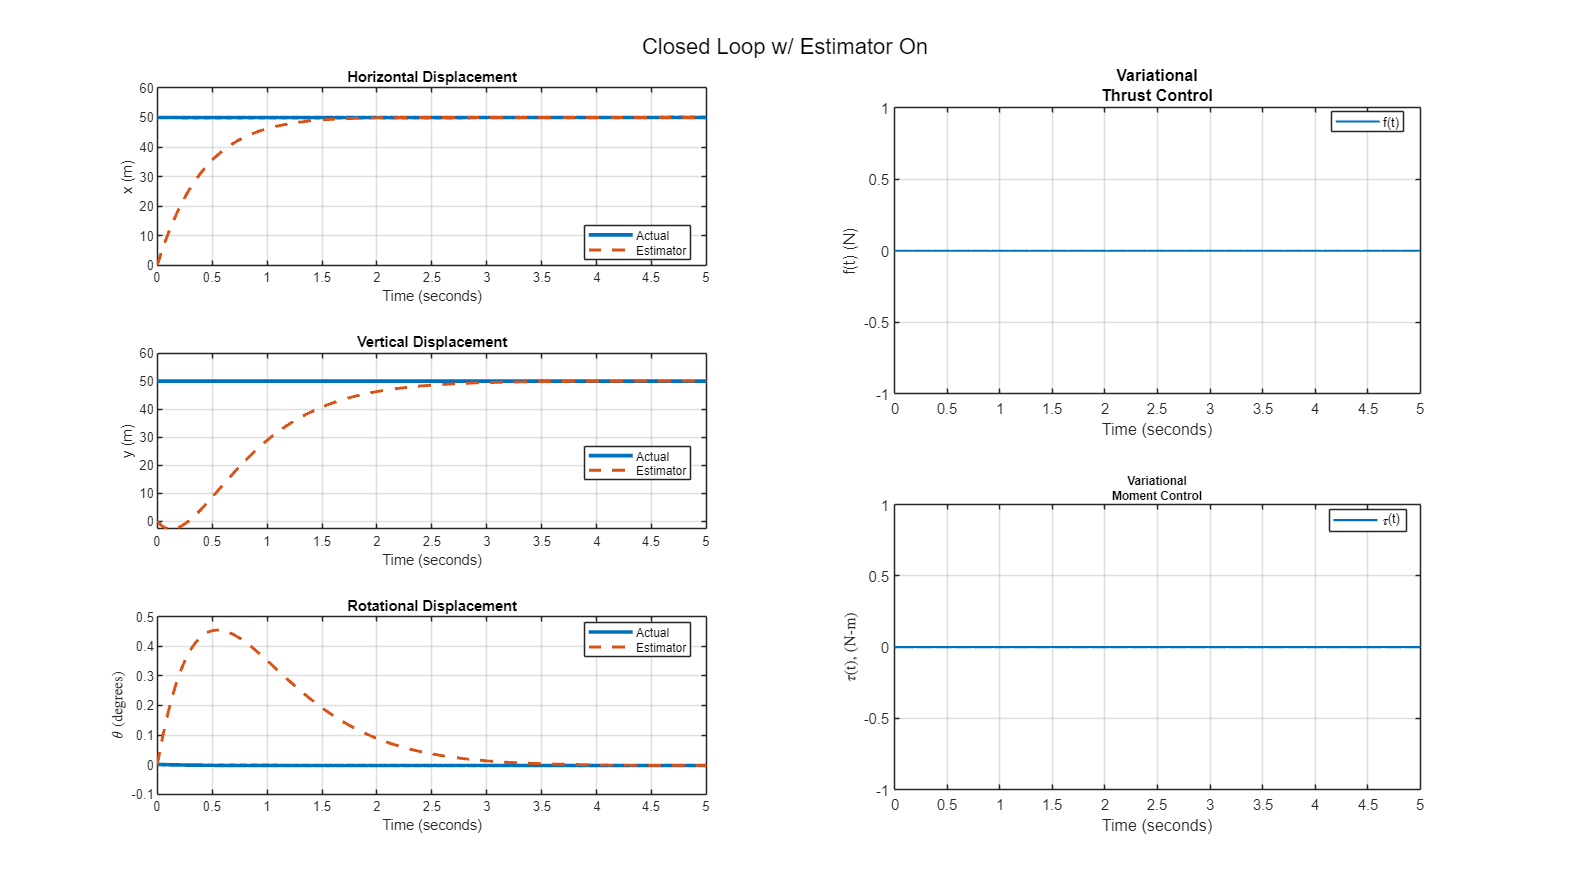

% Define initial conditions (actual states and estimated states)
init_vector = [50; -0.1; 50; 0.1; 0; -0.01];  % Actual states
init_vectorEstimated = zeros(N, 1);                % Estimated states (start at zero)
init_vectorAugmented = [init_vector; init_vectorEstimated];  % Combined- original one first block, estimated one second block

% Simulate system for the first 5 seconds
t = linspace(0, 5, 500);  % Time vector
[y_aug5, t_out5, x_aug5] = initial(aug_ss_5, init_vectorAugmented, t);
% extracting y values
y_actual5 = y_aug5(:,1:3); %first block matrix is the actual one
y_estimated5 = y_aug5(:,4:6);
% extracting x values
x_actual5 = x_aug5(:,1:N);
x_estimated5 = x_aug5(:,N+1:end);
% extracting u values
u5 = y_aug5(:,7:8);

% Plot results
clf;
figure('Units','normalized','Position',[5,5,0.8,0.8]);

subplot(3, 2, 1);
plot(t_out5, y_actual5(:,1), '-','LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(t_out5, y_estimated5(:,1), '--','LineWidth', 2, 'DisplayName','Estimator');
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
legend('show','Location','best')
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]

subplot(3, 2, 3);
plot(t_out5, y_actual5(:,2), '-','LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(t_out5, y_estimated5(:,2), '--','LineWidth', 2, 'DisplayName','Estimator');
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
legend('show','Location','best')
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);


subplot(3, 2, 5);
plot(t_out5, y_actual5(:,3), '-','LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(t_out5, y_estimated5(:,3), '--','LineWidth', 2, 'DisplayName','Estimator');
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
legend('show','Location','best')
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);

% Plot Variational Thrust Control
subplot(2,2,2);
plot(t_out5, y_aug5(:,7), 'LineWidth', 1.5, 'DisplayName','f(t)'); % Use dashed line for the zero line
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
legend('show','Location','best')
% Plot Variational Moment Control
subplot(2,2,4);
plot(t_out5, y_aug5(:,8), 'LineWidth', 1.5, 'DisplayName','\tau(t)');
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;
legend('show','Location','best')
sgtitle('Closed Loop w/ Estimator On');

d)  Use the INITIAL function to simulate the closed-loop response of the closed-loop LTI model from 5b from $0\le t\le 295$ seconds.  In this simulation, the control should be ON and the observer should also be ON.  In order to guarantee continuity between the end of the previous simulation and the start of this simulation, you must use the final state vector from 5c as your initial conditions for this simulation.  Points will be taken off if your plots indicate a discontinuity in the outputs; however, it is expected that the control signals will be discontinuous at $t=5$ seconds.

%Simulation for 0<t<295

init_vector295 = x_aug5(end,:);

t = linspace(0, 295,1000);  % Time vector
[y_aug295, t_out295, x_aug295] = initial(aug_ss_rest, init_vector295, t);
% y extract
y_actual295 = y_aug295(:,1:P);
y_estimated295 = y_aug295(:,P+1:2*P);
% x extract
x_actual295 = x_aug295(:,1:N);
x_estimated295 = x_aug295(:,N+1:end);
% u extract
u295 = y_aug295(:,2*P+1:end);

%augment the whole 300s time-series
y_actual300 = [y_actual5;y_actual295];
y_estimated300 = [y_estimated5; y_estimated295];
u300 = [u5;u295];
tOut300 = [t_out5;t_out295];
x_actual300 = [x_actual5;x_actual295];
x_estimated300 = [x_actual5;x_actual295];


e)  Generate the standard annotated plot (three output subplots on the left and two control signal subplots on the right), with appropriate annotations; but you must also plot the estimated output signals on top of the associated actual output signals.  It must be clear from your plots that the estimated outputs all start from zero and converge to the actual outputs within 5 seconds.  It is not necessary to get the observer states to converge faster than 5 seconds because it will be difficult to see the convergence on the plots.  If you have done this step correctly, you should see 5% settling times that are comparable to the original design from Problem 2.  The 5% settling times on the outputs must all be below 200 seconds, and you must not saturate either of the control signals.

settlingTime_lsim = zeros(size(y_actual295,2));
for i = 1:size(y_actual295,2)
    S = lsiminfo(y_actual295(:,i),t_out295,y_actual295(end,i),y_actual295(1,i),"SettlingTimeThreshold",0.05);
    settlingTime_lsim(i) = S.SettlingTime;
    fprintf('The settling Time for y(%d) is = %2.3f\n',i, S.SettlingTime)
end

The settling Time for y(1) is = 90.176
The settling Time for y(2) is = 167.804
The settling Time for y(3) is = 284.177


S3 = lsiminfo(y(:,3),tOut,y(end,3),y(1,3),"SettlingTimeThreshold",0.05); %Since theta starts from 0- that's why instead of using SettlingTime, TransientTime was used
settlingTime_lsim(3) = S3.TransientTime 

settlingTime_lsim =    90.1755         0         0
  167.8042         0         0
  115.6082         0         0


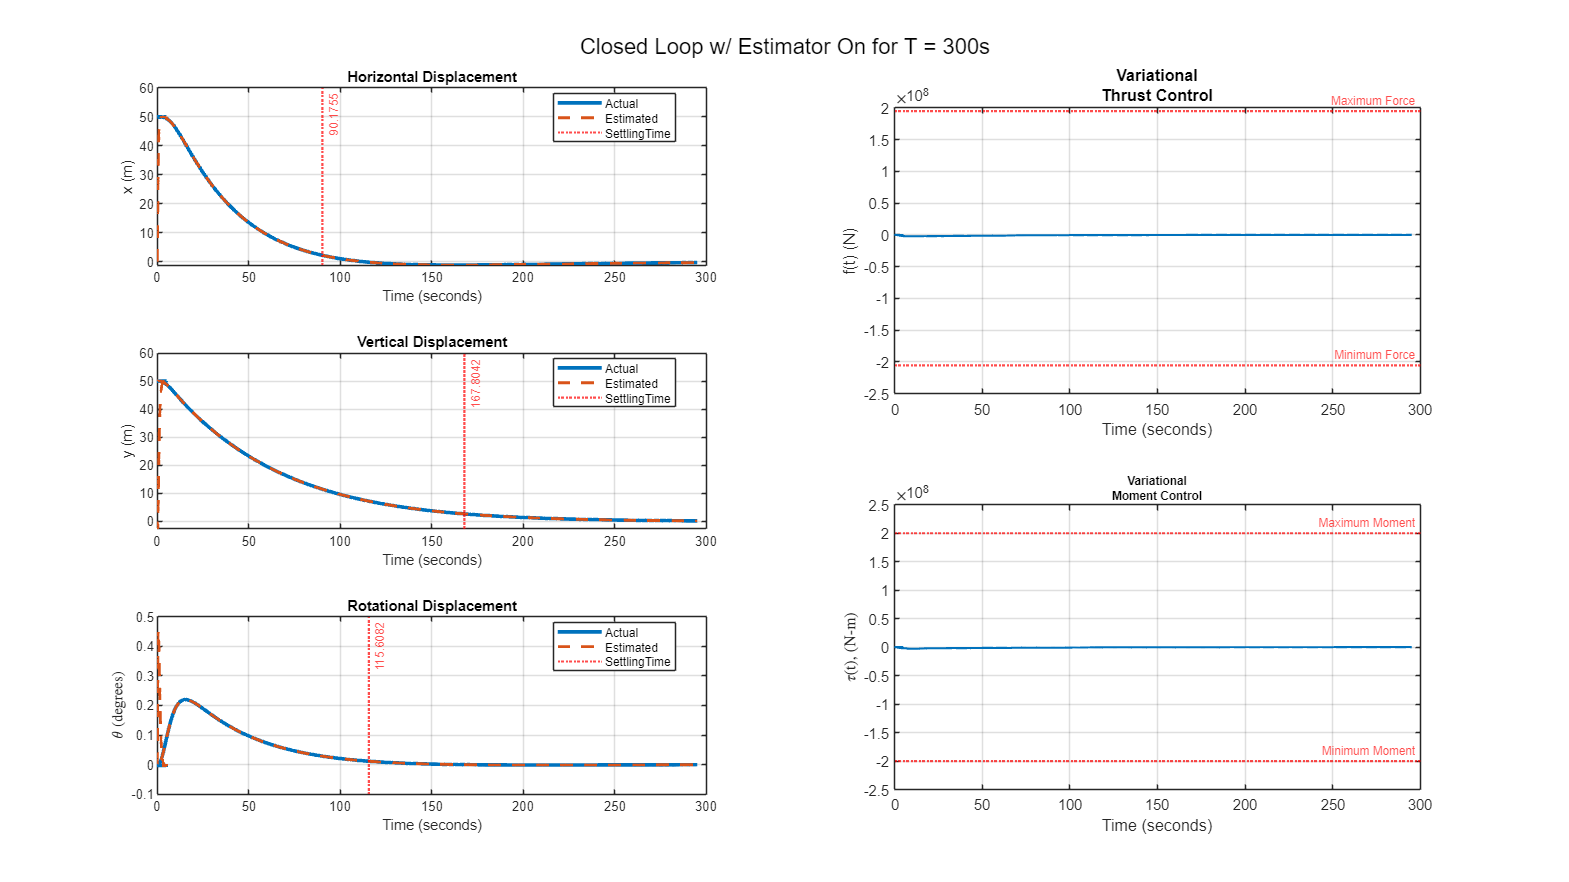

% Plot results
clf;
figure('Units','normalized','Position',[5,5,0.8,0.8]);
subplot(3, 2, 1);
plot(tOut300, y_actual300(:,1),'-', 'LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(tOut300, y_estimated300(:,1),'--', 'LineWidth', 2,'DisplayName','Estimated');
xline(settlingTime_lsim(1), 'r:', 'LineWidth', 1.5, 'Label', num2str(settlingTime_lsim(1)), ...
    'LabelOrientation', 'aligned', 'FontSize', 8, 'DisplayName','SettlingTime');
hold off;
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
legend('show', 'location', 'best');
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]

subplot(3, 2, 3);
plot(tOut300, y_actual300(:,2),'-', 'LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(tOut300, y_estimated300(:,2),'--', 'LineWidth', 2,'DisplayName','Estimated');
xline(settlingTime_lsim(2), 'r:', 'LineWidth', 1.5, 'Label', num2str(settlingTime_lsim(2)), ...
    'LabelOrientation', 'aligned', 'FontSize', 8, 'DisplayName','SettlingTime');
hold off;
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
legend('show', 'location', 'best');
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);


subplot(3, 2, 5);
plot(tOut300, y_actual300(:,3),'-', 'LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(tOut300, y_estimated300(:,3),'--', 'LineWidth', 2,'DisplayName','Estimated');
xline(settlingTime_lsim(3), 'r:', 'LineWidth', 1.5, 'Label', num2str(settlingTime_lsim(3)), ...
    'LabelOrientation', 'aligned', 'FontSize', 8, 'DisplayName','SettlingTime');
hold off;
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
legend('show', 'location', 'best');
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);

% Plot Variational Thrust Control
subplot(2,2,2);
plot(tOut300, u300(:,1), 'LineWidth', 1.5); % Use dashed line for the zero line
hold on;
yline(Fmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Fmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);
plot(tOut300, u300(:,1), 'LineWidth', 1.5);
hold on;
yline(Tmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Tmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
ylim([-2.5e8 +2.5e8])
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('Closed Loop w/ Estimator On for T = 300s');

f)  In addition to the standard five subplot figure, you must also include the animation plot in the LiveScript as documentation of the performance.

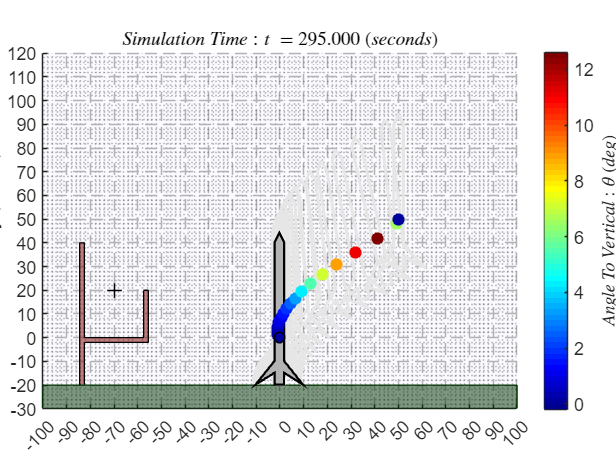

als_f24_animate(tOut300, y_actual300(:,1), y_actual300(:,2),y_actual300(:,3));

For problems 6, 7, and 8, you will design and simulate another Output Feedback Controller (i.e. a state estimator with full state feedback control), but now you must also include Integral Control for reference tracking as defined in the notes.  

This closed-loop simulation will require you to redesign the state-feedback control gains $\mathbf{G}$ (you cannot use the gains from Problem 2!); however, you should plan to use the same state estimator gains $\mathbf{K}$ that you designed in Problem 4.  You are welcome to redesign the state estimater gains (poles), but this is not recommended because it will add unnecessary time to your project completion.

You must expect to iterate on problems 6, 7, and 8 until you achieve one acceptable design.  Do NOT include more than one design!

## Problem 6 [3 pts].  Design an LQI compensator

You must use LQR optimal control to design the state-feedback gains for this simulation.  The MathWorks has provided a separate tool called `LQI` for computing the state-feedback gains when you implement state feedback with integral control.  Note that `LQI` is identical to `LQR` except that `LQI` already knows that you are designing for reference tracking with an integral controller.  **You are NOT allowed to use **`LQR`** for this design, so you must use **`LQI``!`  You must also use the LTI object for the open-loop system as input to the `LQI` function.  Read the online help for `LQI` before starting this problem!

a)  Define the LQI cost function weighting matrices $\mathbf{Q}$ and $\mathbf{R}$.  Note that `LQI` also accepts a weighting matrix $\mathbf{N}$, which allows cross-weighting between states and controls, but there is no need to use that weighting matrix for this problem!  Make sure you understand the dimensions of each of these weighting matrices.

Hint:  Start with all uniform weighting, but you will need significantly larger weights on the integral states...

## Explanation:

Since we have 6 states and 3 integral controller. Therefore, the $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x_I } 
\end{array}\right\rbrack$ is a 9x1 matrix. That leads to the size of the $\mathit{\mathbf{Q}}$ matrix which is a 9x9 matrix. where last 3x3 matrix is part of the controller dynamics. Now, first 6x6 block matrix just kept as an increasing order from 10 to 60 as trivial (compared to the controller block matrix!). The elements for that 3x3 block matrix are ${10}^9 ,{10}^7 ,{10}^6$. The reason for that is since the rocket is going from left to right, that's why  the biggest number is assigned to the first one, which is,${10}^9$. Similar thought was applied for 2nd and 3rd element values. However, it requires quite a lot of trial and error because the **lqi() **function was throwing errors for most of the values as it could not solve the Ricatti Equation.

In addition to that since we have 2 force input, the size of the R matrix turns out to be 2x2. Again, value for this $\mathit{\mathbf{R}}$ matrix also kept as a trivial one- just 10 and 20.

Q = diag([20,20,30,40,50,60,10e9,10e7,10e6])  % should be a 9x9 matrix- last 3 being the integral control elements

Q = 1.0e+10 *

    0.0000         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0
         0         0    0.0000         0         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0         0
         0         0         0         0    0.0000         0         0         0         0
         0         0         0         0         0    0.0000         0         0         0
         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0    0.0100         0
         0         0         0         0         0         0         0         0    0.0010


R = diag([10 20]) %should be a 2x2 matrix

R =     10     0
     0    20


b)  Use the LQI function to generate the optimal control gains.  Define matrices ${\mathbf{G}}_0$ and ${\mathbf{G}}_I$ matrices in the Matlab workspace by splitting the optimal gain matrix from LQI, and display the results.

ss_LQI = ss(Aol,Bol,Col,Dol);
[K,S,CLP] = lqi(ss_LQI,Q,R)

K = 1.0e+07 *

    0.0000    0.0000    0.0145    0.0024    0.0000    0.0000    0.0000   -0.0003   -0.0000
   -0.0911   -0.0450   -0.0000   -0.0000    8.8762    2.9102    0.0022    0.0000    0.0000


S = 1.0e+18 *

    0.0004    0.0002    0.0000    0.0000   -0.0163   -0.0053   -0.0000   -0.0000   -0.0008
    0.0002    0.0001    0.0000    0.0000   -0.0080   -0.0026   -0.0000   -0.0000   -0.0004
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0163   -0.0080   -0.0000   -0.0000    1.5730    0.5157    0.0004    0.0000   -0.0000
   -0.0053   -0.0026   -0.0000   -0.0000    0.5157    0.1691    0.0001    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0001    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0008   -0.0004   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0039


CLP =   -0.0000 + 0.0000i
  -0.0219 + 0.0219i
  -0.0219 - 0.0219i
  -0.0250 + 0.0434i
  -0.0250 - 0.0434i
  -0.0501 + 0.0000i
  -2.0000 + 0.0000i
  -3.0000 + 0.0000i
  -6.0000 + 0.0000i


## Problem 7 [12 pts].  Construct the OFC with Reference Inputs

a)  Generate an augmented state-space LTI object representing the complete closed-loop system, i.e. Plant + Output Feedback Controller (state feedback with estimated states) + Reference Tracking.  There is no need to display this result since it will be too large to fit on the page.  Your complete closed-loop state-space model must have:

- State vector consisting of:  $\mathbf{x}$, $\hat{\mathbf{x}}$, and ${\mathbf{x}}_I$

- Output vector consisting of:  $\mathbf{y}$, $\hat{\mathit{\mathbf{y}}}$, and $\mathbf{u}$

- Input vector consisting of:  $\mathbf{r}=\left\lbrack \begin{array}{c}
x_{\textrm{ref}} \left(t\right)\\
y_{\textrm{ref}} \left(t\right)\\
\theta_{\textrm{ref}} \left(t\right)
\end{array}\right\rbrack$

- State Feedback Control law:  $u=-\left\lbrack \begin{array}{cc}
{\mathbf{G}}_0  & {\mathbf{G}}_I 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\hat{\mathbf{x}} \\
{\mathbf{x}}_I 
\end{array}\right\rbrack$

You can either use the method described in L18, or you can write out each of the state equations and output equations, then combine them into a complete augmented closed-loop system.

## Answer:

I am arranging my augmented state matrix as $\left\lbrack \begin{array}{c}
x\\
x_I \\
\hat{x} 
\end{array}\right\rbrack$ to keep consistency with the Class lecture 17-Slide no 9. 

The $A\;\textrm{and}\;B$ matrix are copy-pasted from L17/S9. However, to derive the closed loop C matrix,


$$\begin{array}{l}
y=\textrm{Cx}+\textrm{Du}\\
\Rightarrow y=\textrm{Cx}+D\left(-G_0 \hat{\;x\;} -G_I x_I \right)\\
\Rightarrow \mathit{\mathbf{y}}=\textrm{Cx}-{\textrm{DG}}_0 \hat{\;\mathit{\mathbf{x}}\;} -{\textrm{DG}}_{\mathit{\mathbf{I}}} {\mathit{\mathbf{x}}}_{\mathit{\mathbf{I}}} \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \left(1\right)
\end{array}$$



$$\begin{array}{l}
\hat{\;y\;} =\hat{\;C\;} x+\hat{\;D\;} u\\
\Rightarrow \hat{\;y\;} =\hat{\;C\;} \hat{\;x\;} +\hat{\;D\;} \left(-G_0 \hat{\;x\;} -G_I x_I \right)\\
\Rightarrow \hat{\;\mathit{\mathbf{y}}\;} =\hat{\;\mathit{\mathbf{C}}\;} \hat{\;\mathit{\mathbf{x}}\;} -{\textrm{DG}}_0 \hat{\;\mathit{\mathbf{x}}\;} -{\textrm{DG}}_{\mathit{\mathbf{I}}} {\mathit{\mathbf{x}}}_{\mathit{\mathbf{I}}} \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \left(2\right)
\end{array}$$



$$\mathit{\mathbf{u}}=-{\mathit{\mathbf{G}}}_0 \hat{\;\mathit{\mathbf{x}}\;} -{\mathit{\mathbf{G}}}_{\mathit{\mathbf{I}}} \hat{\;\mathit{\mathbf{x}}{\;}_{\mathit{\mathbf{I}}} } \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \left(3\right)$$


Therefore, my equation becomes: $\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\;x_I } \\
\dot{\;\hat{x} } \;
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A & -{\textrm{BG}}_I  & -{\textrm{BG}}_0 \\
-C & {\textrm{DG}}_I  & {\textrm{DG}}_0 \\
\textrm{KC} & -\hat{\;B} G_I -K\left(D-\hat{\;D} \right)G_I  & \hat{A} -K\hat{\;C\;} -\hat{\;B\;} G_0 -K\left(D-\hat{\;D} \right)G_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
x_I \\
\hat{x} 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
y\\
\hat{\;y\;} \\
u
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
C & -{\textrm{DG}}_I  & -{\textrm{DG}}_0 \\
0 & -{\textrm{DG}}_I  & \hat{\;C\;} -{\textrm{DG}}_0 \\
0 & -G_I  & -G_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
x_I \\
\hat{x} 
\end{array}\right\rbrack 
\end{array}$

%Extract G_I and G_0
G_0 = K(:,1:N);
G_I = K(:,N+1:end);
%Construction of the closed loop matrices
A_LQI = [Aol, -Bol*G_I, -Bol*G_0; 
         -Col, Dol*G_I, Dol*G_0; 
         obsv_gains*Col, -Bol*G_I, Aol - obsv_gains*Col - Bol*G_0];

C_LQI = [Col, -Dol*G_I -Dol*G_0;...
    zeros(P,N), -Dol*G_I, Col-Dol*G_0;...
    zeros(M,N), -G_I, -G_0];
% state space system construction
ss_LQI = ss(A_LQI,[],C_LQI, []);

b)  Compute and display the eigenvalues of the resultling closed-loop LTI system model.  There should NOT be any unstable eigenvalues!

eigVal = eig(A_LQI);
T = table(eigVal);
T.Properties.VariableNames = {'Eigen Values'};
disp(T)

        Eigen Values     
    _____________________

             -6+0i       
             -3+0i       
          -2.49+0.099i   
          -2.49-0.099i   
         -2.255+0.052i   
         -2.255-0.052i   
          -2.02+0.004i   
          -2.02-0.004i   
      -0.025041+0.043386i
      -0.025041-0.043386i
      -0.050106+0i       
      -0.021889+0.021889i
      -0.021889-0.021889i
    -8.7211e-17+0i       
             -2+0i       



## Problem 8 [15 pts].  Simulate the Output Feedback Controller with Reference Inputs

For this problem, you will need to simulate the closed-loop response of your complete control system using `LSIM()`.  In this simulation, both the controller and the state estimator will be turned on at the same time, i.e. this is NOT a two-stage simulation like you did in problem 5.  Use the following requirements and guidelines for choosing initial conditions:

**Plant Initial Conditions:**  The plant (rocket) must start with the same initial states as defined in the Midterm Project, and as used above.

**Observer Initial Conditions:**  You may choose one of the two options below for the initial observer states:

- $\hat{\mathbf{x}} \left(0\right)=0$.  Initializing the observer states to zero will likely cause the initial control signals to exceed the saturation limits at the very beginning of the simulation, but then they should remain within the bounds after the observer states (outputs) have converged.  There is no grade penalty for exceeding the control saturation limits during the transient convergence period of the estimator.

- $\hat{\mathbf{x}} \left(0\right)=\mathbf{x}\left(0\right)$.  Initializing the observer states to be identical to the plant states will make the problem easier, but is not realistic in practice.  In this case, your design must not allow either control signal to exceed the saturation limits.  There will be a grade penalty for exceeding the control authority bounds if you use this option since you are giving the estimator a head start.  This is the preferred option.

**Integrator Initial Conditions:**  You may choose one of the two options below for the initial integrator states:

- ${\mathbf{x}}_I \left(0\right)=0$.  Initializing the integrator states to zero will likely cause the initial control signals to exceed the saturation limits at the very beginning of the simulation.  There is no grade penalty for exceeding the control saturation limits during the transient convergence period of the estimator.  This option is not recommended.

- ${\mathbf{x}}_I \left(0\right)=-{G_I }^+ \times G_0 \times \hat{\mathbf{x}} \left(0\right)$.  Initializing the integrator states using this formula will make the problem easier, and is a reasonable practical approach since everything is known in the formula.  In this case, your design should not allow either control signal to exceed the saturation limits.  In this formula, the superscript+ means pseudo-inverse.  Note that the pseudo-inverse (`PINV`) must be used because the ${\mathrm{G}}_I$ matrix is not square. This choice for the initial integrator state vector causes the initial control signal to be zero which has clear advantages when first enabling the controller prior to convergence of the estimator:


$$\mathbf{u}\left(0\right)=-{\mathrm{G}}_0 \hat{\mathbf{x}} \left(0\right)-{\mathrm{G}}_I {\mathbf{x}}_I \left(0\right)=-{\mathrm{G}}_0 \hat{\mathbf{x}} \left(0\right)+\left({\mathrm{G}}_I {G_I }^+ \right)G_0 \hat{\mathbf{x}} \left(0\right)\approx -{\mathrm{G}}_0 \hat{\mathbf{x}} \left(0\right)+G_0 \hat{\mathbf{x}} \left(0\right)\approx 0$$


**Plant Final Conditions:**  You must land the rocket on the platform without making contact with any part of the platform except for the very bottom.  The rocket must not fall below the bottom bar in the platform.  You must determine the final coordinates from the animation plot!

**Additional Evaluation Criteria:**

- The rocket is NOT allowed to make contact with the landing platform at any point during the simulation until it lands properly.  

- The rocket is NOT allowed to make contact with the ground at any point during the simulation.

- All parts of the rocket must remain inside the animation plot window at all times.

- The angular position of the rocket must remain bounded by:  $-{30}^{\circ } \le \theta \left(t\right)\le {30}^{\circ }$

- The rocket must reach the final state by no later than 600 seconds and no sooner than 300 seconds: ($300s\le T_{\textrm{final}} \le 600s$).  Hint:  It will be easier for your solution if you choose the maximum amount of time allowed to land.

- The control signals must remain within the saturation bounds established in the Midterm Project.

- There is NO formal settling time requirement; however, your actual output responses $\mathbf{y}$ must track the reference responses $\mathbf{r}$ reasonably accurately.  For example, if your reference profiles have dwell regions, then there should be zero steady-state error after the transients have dissipated.  If your reference profiles have ramp regions, then you should expect to see a steady-state error during the ramp.  This will look like a delayed response in the time domain plots.  How closely you track the references will depend on your choice of weighting coefficients in the Q matrix.  Note that a steady-state error during the ramp is acceptable and expected.

- The reference profile must be continuous, but it does not need to have continuous derivatives, i.e. it can have slope discontinuities.

- For this simulation, the observer and the controller must both be enabled at t=0 (i.e. do NOT attempt a two-stage simulation like problem 5.

- You MUST use `LSIM` to simulate the closed-loop time response

a) Before constructing the reference trajectories, you must first construct a time vector for the simulation.  I recommend choosing a uniform step size of $t_s =0\ldotp 1$ seconds, then construct the time vector using the following (do NOT use `LINSPACE` here!):


$$t=t_s *\left\lbrack 0:\textrm{round}\left(\frac{t_{\textrm{final}} }{t_s }\right)\right\rbrack$$


## Trajectory Definition: 

The way the reference trajectory is defined is it is divided into 4 main segments. First, the rocket takes off from (50,50,0) to (20,60,0). Then, the rocket is supposed to maintain a upright horizontal position from (20,60,0) to (-70,60,0). Finally, it drops from (-70,60,20) to the platform. To stabilize the rocket, another segment is added which is exactly the similar as (-70,60,20).

t_s = 0.1;

t_final = 600;               % Final time
t_vector = t_s * (0:round(t_final/t_s)); % Time vector
total_time = length(t_vector);        % Total number of time steps

T1 = round(0.3 * total_time);     % First segment length
T2 = round(0.3 * total_time);     % Second segment length
T3 = round(0.3 * total_time);        % Remaining steps for the third segment
T4 = total_time - (T1 + T2 + T3);
% Reference Tracking Vector Definition

x_ref = [linspace(50, 20, T1), linspace(20, -70, T2), linspace(-70, -70, T3), linspace(-70, -70, T4)];
theta_ref = zeros(1, total_time); % Same length as t_opt
y_ref = [linspace(50, 60, T1), linspace(60, 60, T2), linspace(60, 20, T3),linspace(20, 20, T4)];

% Combined reference vector
r = [x_ref; y_ref; theta_ref]; 

b)  For each time step in the time vector, you must generate a reference vector that you would like each of the outputs to track.  You will need to generate a particular path vs. time profile for the desired x and y position; however, you are strongly advised to choose the following reference profile for the angular position:


$$\theta_{\textrm{ref}} =\textrm{zeros}\left(\textrm{size}\left(t\right)\right)$$


Store all three reference trajectory profile vectors in a matrix called $r$, where each column is one time step, and each row is one of the desired outputs:


$$r\left(t\right)=\left\lbrack \begin{array}{c}
x_{\textrm{ref}} \left(t\right)\\
y_{\textrm{ref}} \left(t\right)\\
\theta_{\textrm{ref}} \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
x_{\textrm{ref}} \left(1\right) & x_{\textrm{ref}} \left(2\right) & \cdots  & x_{\textrm{ref}} \left(\textrm{NPTS}\right)\\
y_{\textrm{ref}} \left(1\right) & y_{\textrm{ref}} \left(2\right) & \cdots  & y_{\textrm{ref}} \left(\textrm{NPTS}\right)\\
\theta_{\textrm{ref}} \left(1\right) & \theta_{\textrm{ref}} \left(2\right) & \cdots  & \theta_{\textrm{ref}} \left(\textrm{NPTS}\right)
\end{array}\right\rbrack$$


c)  Define the total initial condition vector for the augmented closed-loop state-space model: ${\mathbf{x}}_I \left(0\right)=-{G_I }^+ \times G_0 \times \hat{\mathbf{x}} \left(0\right)$

init_vectorStates = init_vector; % 6x1
init_vectorEstimators = init_vector; % 6x1 
init_vectorIntegral = -pinv(G_I)*G_0*init_vectorEstimators; % 3x1
init_vectorCombined = [init_vectorStates;init_vectorIntegral;init_vectorEstimators];

d)  Simulate the closed-loop time response and plot the results using the same plot structure as before except for the new signals that must be added.  Each of the three output subplots on the left must include the reference profile, the actual output, and the estimated output on the same axis.

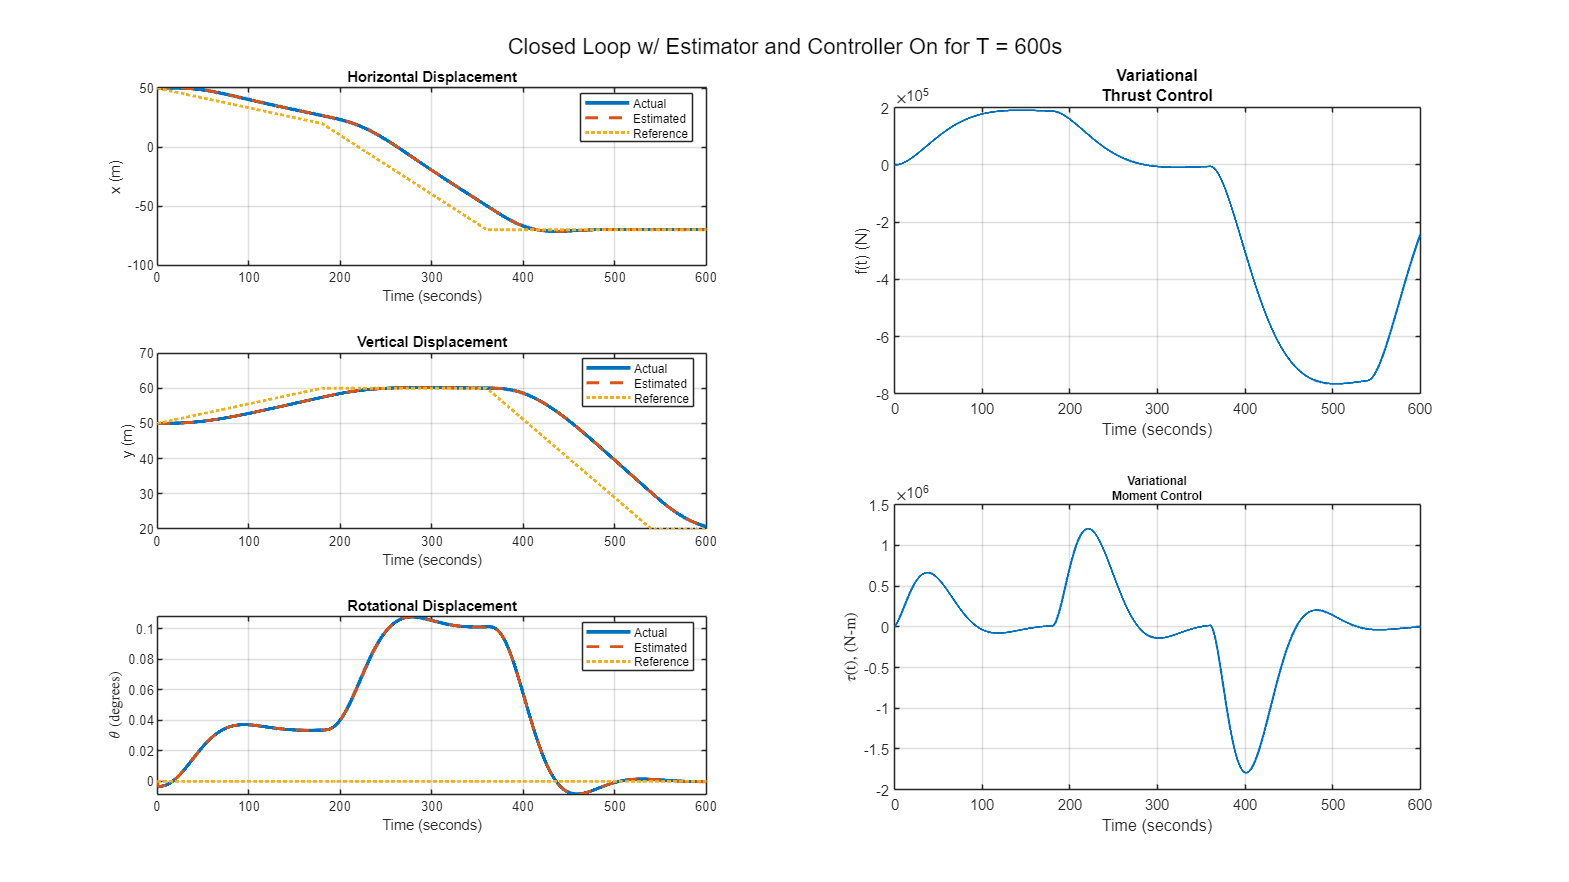

B_LQI = [zeros(6, 3); 
     eye(3);     
     zeros(6, 3)]; 
ss_LQI = ss(A_LQI,B_LQI,C_LQI, []);

[y_final, t_final] = lsim(ss_LQI,r,t_vector,init_vectorCombined);
%load('ForceLimit.mat');
% Plot results
clf;
figure('Units','normalized','Position',[5,5,0.8,0.8]);
subplot(3, 2, 1);
plot(t_final, y_final(:,1),'-', 'LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(t_final, y_final(:,4),'--', 'LineWidth', 2,'DisplayName','Estimated');
plot(t_final, r(1,:),':', 'LineWidth', 2,'DisplayName','Reference');
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
legend('show', 'location', 'best');
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]

subplot(3, 2, 3);
plot(t_final, y_final(:,2),'-', 'LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(t_final, y_final(:,5),'--', 'LineWidth', 2,'DisplayName','Estimated');
plot(t_final, r(2,:),':', 'LineWidth', 2,'DisplayName','Reference');
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
legend('show', 'location', 'best');
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);


subplot(3, 2, 5);
plot(t_final, y_final(:,3),'-', 'LineWidth', 2.5,'DisplayName','Actual');
hold on
plot(t_final, y_final(:,6),'--', 'LineWidth', 2,'DisplayName','Estimated');
plot(t_final, r(3,:),':', 'LineWidth', 2,'DisplayName','Reference');
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
legend('show', 'location', 'best');
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);

% Plot Variational Thrust Control
subplot(2,2,2);
plot(t_final, y_final(:,7), 'LineWidth', 1.5); % Use dashed line for the zero line
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);
plot(t_final, y_final(:,8), 'LineWidth', 1.5);

xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('Closed Loop w/ Estimator and Controller On for T = 600s');

e)  In addition to the standard five subplot figure, you must also include the animation plot in the LiveScript as documentation of the performance.

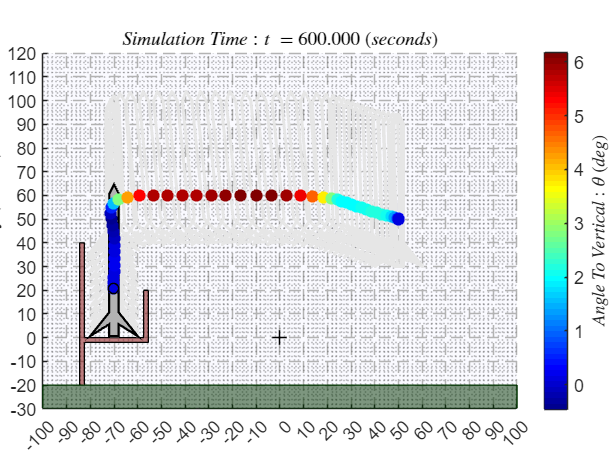

als_f24_animate(t_final, y_final(:,1), y_final(:,2),y_final(:,3));